# This is a simple perceptron model

% Define the perceptron parameters
inputSize = 2;
outputSize = 1;
learningRate = 0.1;
epochs = 20;


## Generate random input data

data = randn(50, 2);
disp(data);

   -0.5040    1.0036
   -1.2240    1.5110
    0.1185   -1.1372
    0.9595    0.6430
   -0.3409   -0.0128
   -0.1733    0.9143
    0.6163    1.1077
    0.8639    0.8205
   -1.4169   -0.8176
    0.2000   -0.1265
    0.1958    0.2641
   -0.1511    3.1585
    0.8928    1.2266
   -0.3642    2.3206
   -0.8262    0.4145
    0.2760    0.2118
    0.4598    0.6132
   -0.2175   -0.5278
    0.7961    1.2416
   -1.5180   -0.1576
   -1.0749   -1.3736
   -3.0722    0.8708
    0.5214   -1.5685
   -0.9910   -1.8443
   -0.2531    0.2884
    1.0093   -0.9509
    0.0510   -0.9107
   -0.4404   -0.1619
   -0.8485   -0.4889
   -0.2404   -0.2228
    0.6029    0.2721
   -1.5163   -1.1685
   -0.0683   -1.2242
    0.7824   -2.0995
   -1.4207   -0.3902
    0.6694    0.6643
    0.6832   -0.7023
   -0.8821    0.5013
   -1.5045    0.5403
    0.4331    0.9908
    0.8083    0.9894
    0.5789   -0.6888
    0.7628   -0.8568
   -1.1821    0.0484
    0.5838   -0.6649
   -0.5800    1.4527
   -0.5614    1.3798
   -1.5559   

## Define the target labels based on a simple linear decision boundary

target = data(:, 1) + 2 * data(:, 2) > 0;
disp(target);

   1
   1
   0
   1
   0
   1
   1
   1
   0
   0
   1
   1
   1
   1
   1
   1
   1
   0
   1
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   1
   0
   1
   0
   1
   1
   0
   0
   0
   0
   1
   1
   0
   1
   1



## Create and initialize the perceptron weights for all inputs and the bias term

weights = randn(inputSize + 1, outputSize);
disp("weights"); disp(weights);

weights
   -0.6563
   -0.1250
   -0.5305




% Add bias to the input data
bias = ones(size(data, 1), 1);
full_dataBias = [data, bias];
disp("full_dataBias"); disp(full_dataBias);

full_dataBias
   -0.5040    1.0036    1.0000
   -1.2240    1.5110    1.0000
    0.1185   -1.1372    1.0000
    0.9595    0.6430    1.0000
   -0.3409   -0.0128    1.0000
   -0.1733    0.9143    1.0000
    0.6163    1.1077    1.0000
    0.8639    0.8205    1.0000
   -1.4169   -0.8176    1.0000
    0.2000   -0.1265    1.0000
    0.1958    0.2641    1.0000
   -0.1511    3.1585    1.0000
    0.8928    1.2266    1.0000
   -0.3642    2.3206    1.0000
   -0.8262    0.4145    1.0000
    0.2760    0.2118    1.0000
    0.4598    0.6132    1.0000
   -0.2175   -0.5278    1.0000
    0.7961    1.2416    1.0000
   -1.5180   -0.1576    1.0000
   -1.0749   -1.3736    1.0000
   -3.0722    0.8708    1.0000
    0.5214   -1.5685    1.0000
   -0.9910   -1.8443    1.0000
   -0.2531    0.2884    1.0000
    1.0093   -0.9509    1.0000
    0.0510   -0.9107    1.0000
   -0.4404   -0.1619    1.0000
   -0.8485   -0.4889    1.0000
   -0.2404   -0.2228    1.0000
    0.6029    0.2721    1.0000
   -1.5163   -1.1685    1

## Training the perceptron

for epoch = 1:epochs
    % Forward pass
    output = full_dataBias * weights;
    predictions = output > 0;

    % Compute the error
    error = target - predictions;

    % Update weights using the perceptron learning algorithm
    weights = weights + learningRate * (full_dataBias' * error);
    fprintf("iteration %i",epoch);
    disp(weights);
    
end

iteration 1

    1.4092
    2.3998
    0.6695



iteration 2

    1.4233
    2.4138
    0.4695



iteration 3

    1.4033
    2.4264
    0.3695



iteration 4

    1.3833
    2.4391
    0.2695



iteration 5

    1.3633
    2.4517
    0.1695



iteration 6

    1.3433
    2.4644
    0.0695



iteration 7

    1.2407
    2.5185
    0.0695



iteration 8

    1.2407
    2.5185
    0.0695



iteration 9

    1.2407
    2.5185
    0.0695



iteration 10

    1.2407
    2.5185
    0.0695



iteration 11

    1.2407
    2.5185
    0.0695



iteration 12

    1.2407
    2.5185
    0.0695



iteration 13

    1.2407
    2.5185
    0.0695



iteration 14

    1.2407
    2.5185
    0.0695



iteration 15

    1.2407
    2.5185
    0.0695



iteration 16

    1.2407
    2.5185
    0.0695



iteration 17

    1.2407
    2.5185
    0.0695



iteration 18

    1.2407
    2.5185
    0.0695



iteration 19

    1.2407
    2.5185
    0.0695



iteration 20

    1.2407
    2.5185
    0.0695



## Test the perceptron with new data

testData = randn(20, 2);
testTarget = testData(:, 1) + 2 * testData(:, 2) > 0;
testDataBias = [testData, ones(size(testData, 1), 1)];
testOutput = testDataBias * weights;
testPredictions = testOutput > 0;

% Display results
disp('Target Labels:');

Target Labels:


disp(testTarget');

   0   1   1   1   0   1   0   1   1   1   0   1   0   0   0   1   0   1   1   0



disp('Predicted Labels:');

Predicted Labels:


disp(testPredictions');

   0   1   1   1   0   1   0   1   1   1   0   1   0   0   0   1   0   1   1   0



## Want a plot

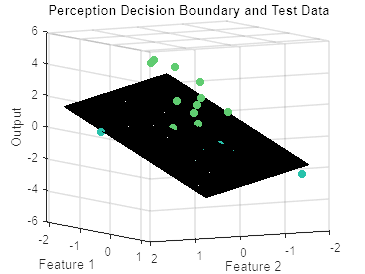

% Plotting the points and decision boundary
figure;

% Scatter plot for points
scatter3(testData(:, 1), testData(:, 2), testOutput, 50, testTarget, 'filled');
hold on;

% Generate points for the decision boundary
[x, y] = meshgrid(linspace(min(testData(:, 1)), max(testData(:, 1)), 100), ...
                  linspace(min(testData(:, 2)), max(testData(:, 2)), 100));

% Calculate the z values for the boundary
z = x + 2 * y;

% Plot the decision boundary surface
mesh(x, y, z, 'FaceAlpha', 0.6, 'EdgeColor', 'k');

% plot aesthetics
title('Perception Classification on Data');
xlabel('Feature 1');
ylabel('Feature 2');
zlabel('Output');

hold off;